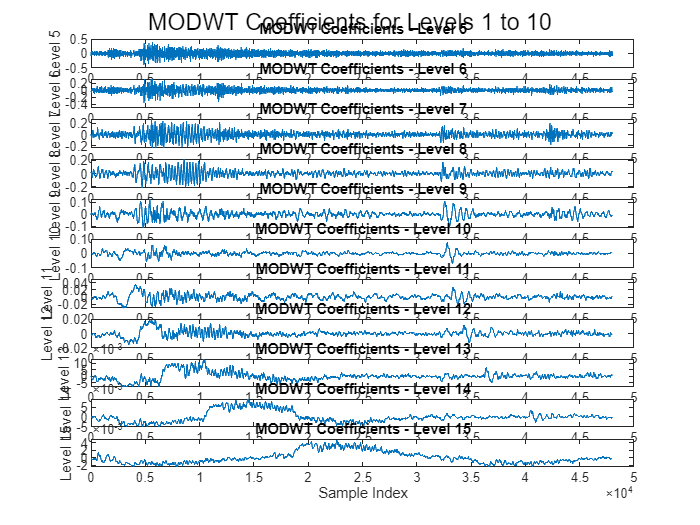

% Sample data for analysis
data = XF1(2, :);  
waveletType = 'db1';   % Daubechies wavelet of order 1

% Perform MODWT on the data
modwtCoeffs = modwt(data, waveletType, 15);  % MODWT up to level 10

% Plot iteration results from 1 to 10
figure;
s = 5;
l = 15;
for i = s:l
    subplot(l-s+1, 1, i-s+1);
    plot(modwtCoeffs(i, :));
    title(['MODWT Coefficients - Level ' num2str(i)]);
    xlabel('Sample Index');
    ylabel(['Level ' num2str(i)]);
end

sgtitle('MODWT Coefficients for Levels 1 to 10');